clc; clear; close all;
f = @(x) -2*x

f = function_handle with value:
    @(x)-2*x



dt = 0.1

dt = 0.1000

tf = 2

tf = 2


x = [1];

n = tf/dt

n = 20


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                       2.a
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% RK1
tic;
for i = 1:n-1

    K1          = f(x(i));
    x(i+1)      = x(i) + dt * K1;

end
toc;

Elapsed time is 0.009944 seconds.


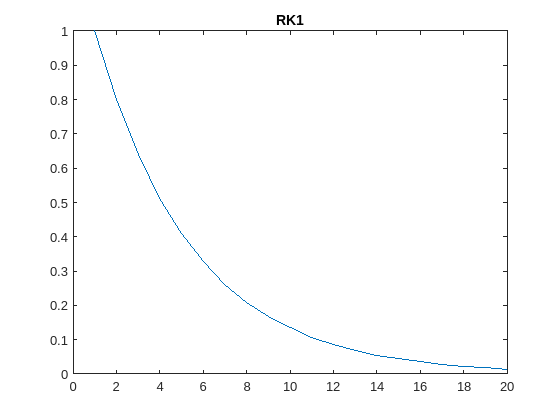


figure
plot(1:n ,x(1,:))
title("RK1")


% RK2
tic;
for i = 1:n-1

    K1          = f(x(i));
    K2          = f(x(i)+(dt/2)*K1);
    x(i+1)      = x(i) + dt*(K2);

end
toc;

Elapsed time is 0.004252 seconds.


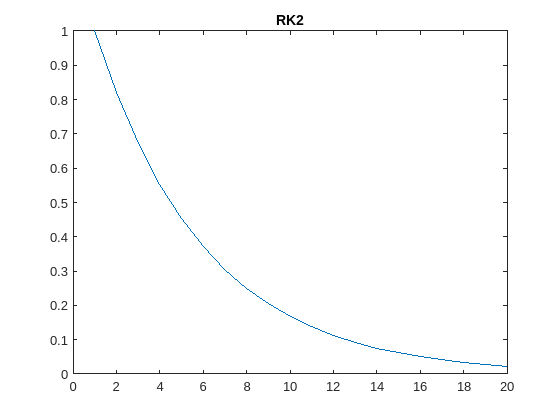


figure 
plot(1:n ,x(1,:))
title("RK2")


% RK4
tic;
for i = 1:n-1

    K1          = f(x(i));
    K2          = f(x(i)+(dt/2)*K1);
    K3          = f(x(i)+(dt/2)*K2);
    K4          = f(x(i)+dt*K3);

    x(i+1)      = x(i) + dt*((1/6)*K1+(1/3)*K2+(1/3)*K3+(1/6)*K4);

end
toc;

Elapsed time is 0.008968 seconds.


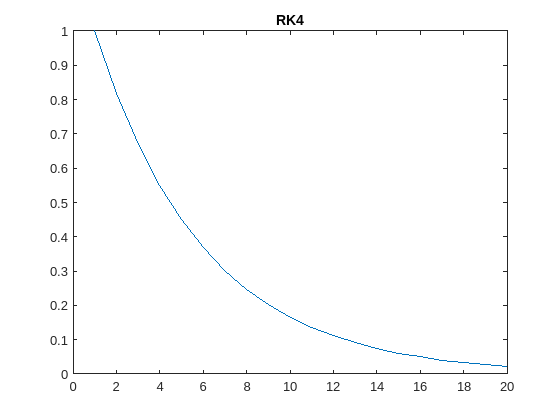


figure
plot(1:n ,x(1,:))
title("RK4")


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                       2.b
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms x(t)

ode = diff(x) == -2*x;

xsol(t) = dsolve(ode,x(0) == 1)

$$xsol(t) = {\mathrm{e}}^{-2\,t}$$

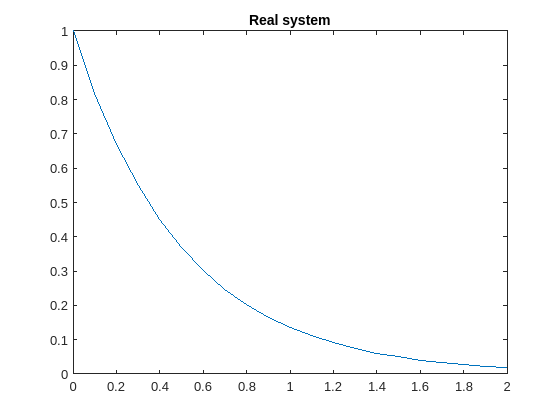

% 
t = 0:dt:tf;
plot(t,(xsol(t)))
title("Real system")

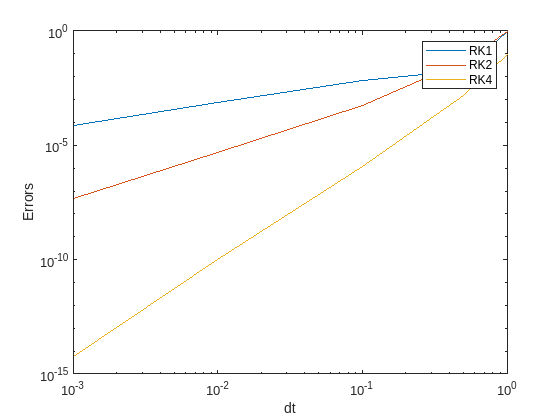




for rk_state = [1 2 4]
    all_dt = [1 0.5 0.1 0.01 0.001];
    errors = [];
    
    ii = 0;
    for dt = all_dt
        ii = ii + 1;
        predicted_x   = [1];
      
        N = round(tf/dt);
        last_t = 0;
        switch rk_state
           case 1
              for i = 1:N
                    K1                  = f(predicted_x(i));
                    predicted_x(i+1)    = predicted_x(i) + dt * K1;
                    last_t              = last_t + dt;
              end

              
          case 2
              for i = 1:N
                    K1                  = f(predicted_x(i));
                    K2                  = f(predicted_x(i) + (dt/2)*K1);
                    predicted_x(i+1)    = predicted_x(i) + dt * K2;
                    last_t              = last_t + dt;
              end

          case 4
              for i = 1:N
                    K1                  = f(predicted_x(i));
                    K2                  = f(predicted_x(i) + (dt/2)*K1);
                    K3                  = f(predicted_x(i) + (dt/2)*K2);
                    K4                  = f(predicted_x(i) + dt*K3);

                    predicted_x(i+1)    = predicted_x(i) + dt * ((1/6)*K1 + (1/3)*K2 + (1/3)*K3 + (1/6)*K4);
                    last_t              = last_t + dt;
              end

        end
        errors(ii) = abs(predicted_x(end) - xsol(last_t));
    end

    loglog(all_dt, errors);
    legend("RK1", "RK2", "RK4")
    xlabel('dt')
    ylabel('Errors')
    hold on;
end

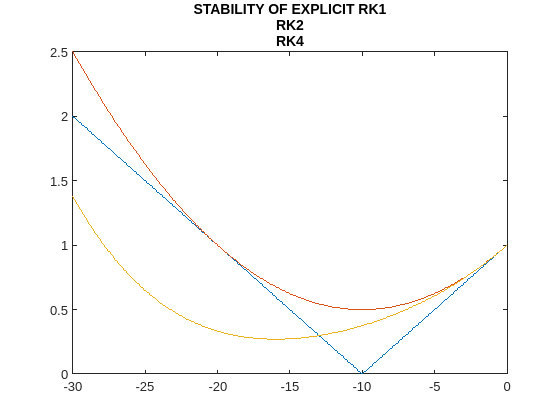


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                       2.c
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% RK1
dt          = 0.1;
all_lamda   = -30:0.1:0;
S = [];

for lambda = all_lamda
    sum = 0;
    for k = 0:1
        sum = sum + ( ((lambda*dt)^k) / factorial(k) );
    end
    S = [S abs(sum)];
end

figure 
plot(all_lamda, S)
title(["STABILITY OF EXPLICIT RK1", "RK2", "RK4"]);
hold on;

% RK2
S = [];

for lambda = all_lamda
    sum = 0;
    for k = 0:2
        sum = sum + ( ((lambda*dt)^k) / factorial(k) );
    end
    S = [S abs(sum)];
end

plot(all_lamda, S)
hold on;

% RK4

S = [];

for lambda = all_lamda
    sum = 0;
    for k = 0:4
        sum = sum + ( ((lambda*dt)^k) / factorial(k) );
    end
    S = [S abs(sum)];
end

plot(all_lamda, S)
hold on;



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                       3.a
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tic;
clear t

% options = odeset()

options = odeset("AbsTol",1e-8,"RelTol",1e-8);

tspan   = [0 25];
x0      = [1 0];
u       = 5;

f = @(t, x) [
                x(2);
                u*(1-x(1)^2)*x(2)-x(1)
             ];

y = ode45(f, tspan, x0, options);
disp("Van-der-Pol oscillator time " + toc)

Van-der-Pol oscillator time 0.01802


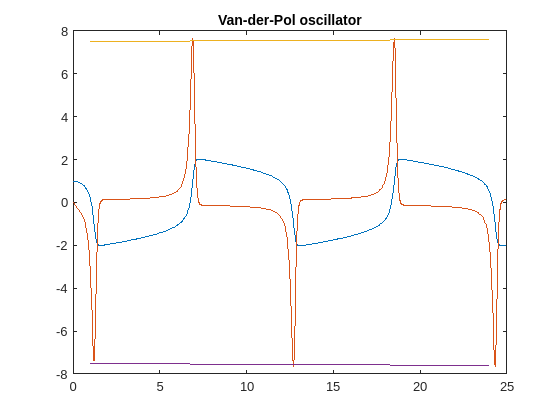


figure
plot(y.x, y.y(1,:))
hold on
plot(y.x, y.y(2,:))
plot([1,24],[7.5,7.6])
plot([1,24],[-7.5,-7.6])
title("Van-der-Pol oscillator")



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                       3.b
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tic;
dt = 0.125;
tf = 25;
t = 0:dt:tf;

x = zeros(tf/dt,2);
x(1,:) = [1 0];

N = round(tf/dt);

f = @(x) [
            x(2);
            5*(1-x(1)^2)*x(2)-x(1)
        ];

for i = 1:N
    K1                  = transpose(f(x(i,:)));
    K2                  = transpose(f(x(i,:) + (dt/2)*K1));
    K3                  = transpose(f(x(i,:) + (dt/2)*K2));
    K4                  = transpose(f(x(i,:) + dt*K3));

    x(i+1,:)            = x(i,:) + dt * ((1/6)*K1 + (1/3)*K2 + (1/3)*K3 + (1/6)*K4);
end

disp("RK4 scheme on the same dynamics time " + toc)

RK4 scheme on the same dynamics time 0.014189


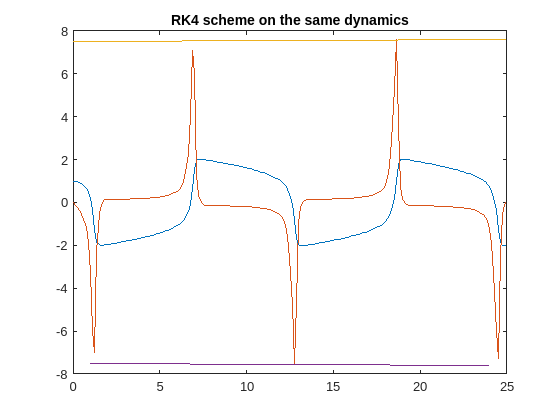


figure
plot(t,x(:,1))
hold on
plot(t,x(:,2))
plot([0,25],[7.5,7.6])
plot([1,24],[-7.5,-7.6])
title("RK4 scheme on the same dynamics")



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                       4.a
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
